% Nome: Caio Gomes Gonçalves    
% Matrícula: 16.2.1767
% Questão 2) Ponto 1

clc;
clear all;

%Robô Planar RR

%Limites Mecânicos do Servo do Levantamento do Braço:
    % Mínimo: 0°.
    % Máximo: +180°.
%Limites Mecânicos da Servo do Cotovelo do Braço:
    % Mínimo: -50°.
    % Máximo: +90°.

%Definição dos parâmetros do Robô RR

a1=20;
a2=10;
a3=5;
alfa=-pi/2;% parâmetro necessário para que a posição zero do robô tenha a configuração desejada na qual o eixo x2 (cotovelo)  está a -90º em relação a x1 (levantamento do braço)

%Espaço de Trabalho

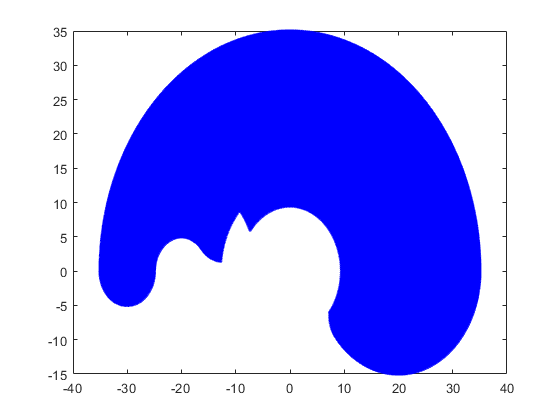

i=0;

theta1_limInf=0;%limite inferior de theta 1 em graus
theta1_limSup=180;%limite superior de theta 1 em graus
theta2_limInf=-50;%limite inferior de theta 2 em graus
theta2_limSup=90;%limite superior de theta 2 em graus
theta3_limInf=-135;%limite inferior de theta 3 em graus
theta3_limSup=135;%limite superior de theta 3 em graus

theta1_limInf=deg2rad(theta1_limInf);
theta1_limSup=deg2rad(theta1_limSup);
theta2_limInf=deg2rad(theta2_limInf);
theta2_limSup=deg2rad(theta2_limSup);
theta3_limInf=deg2rad(theta3_limInf);
theta3_limSup=deg2rad(theta3_limSup);


for theta1=theta1_limInf:(theta1_limSup-theta1_limInf)/100:theta1_limSup,
    for theta2=theta2_limInf:(theta2_limSup-theta2_limInf)/100:theta2_limSup,
        for theta3=theta3_limInf:(theta3_limSup-theta3_limInf)/100:theta3_limSup,
            i=i+1;
            x(i)=a1*cos(theta1)+a2*cos(theta1+theta2+alfa)+a3*cos(theta1+theta2+theta3);%cinemática direta de posição x
            y(i)=a1*sin(theta1)+a2*sin(theta1+theta2+alfa)+a3*sin(theta1+theta2+theta3); %cinemática direta de posição y
        end
     end
end
plot(x,y,'.b');
hold on;

%Definição da Trajetória Retilínea
p0_r=[-7.815, 26.02];%xi,yi
p1_r=[12.02,11.7];%xf,yf

Dx=p1_r(1)-p0_r(1); 
Dy=p1_r(2)-p0_r(2);
A=Dy/Dx;
b=p0_r(1,2)-A*p0_r(1,1);
k=0;
n_pontos_r=80;
for i=p0_r(1,1):(p1_r(1,1)-p0_r(1,1))/(n_pontos_r-1):p1_r(1,1),
    k=k+1;
    tx_r(k)=i;
    ty_r(k)=A*tx_r(k)+b ;
end

%Definição do Tempo da Trajetória Retilínea e do Intervalo de Amostragem

Tempo_r=30e-3; % Intervalo de amostragem igual a 40 milissegundos

T_r(1)=0;
for i=2:n_pontos_r,
    T_r(i)=T_r(i-1)+Tempo_r;
end

%Definição dos Intervalos de Tempo da Trajetória Retilínea

dT_r=diff(T_r);

%Controlador Proporcional para Trajetória Retilínea

K_r=[10,0;0,10];

Definido o ponto inicial

xPos = -7.815; %x position of end-effector
yPos = 26.02;%y position of end-effector

P = [xPos yPos]; %end-effector position vector

%Posição Inicial
format compact;
L1 = 20; %link 1 length
L2 = 10; %link 2 length
L3 = 5; 
a1 = L1;
a2 = L2;
a3 = L3;

phi_d = 45

phi_d = 45

phi = deg2rad(phi_d)

phi = 0.7854

Wx = xPos - L3*cos(phi)

Wx = -11.3505

Wy = yPos - L3*sin(phi)

Wy = 22.4845


%Posição Inicial
theta2 = - acos((Wx^2 + Wy^2 - L1^2 - L2^2)/(2*L1*L2));
theta1 = atan2(Wy,Wx) + acos((Wx^2 + Wy^2 + L1^2 - L2^2)/(2*L1*sqrt(Wx^2+Wy^2)));
theta3 = phi - theta2 - theta1;

theta1_d = rad2deg(theta1)

theta1_d = 138.7450

theta2_d = rad2deg(theta2)

theta2_d = -70.3688

theta3_d = rad2deg(theta3)

theta3_d = -23.3762


alfa = 0;

q_r(:,1) = [theta1;(theta2-alfa);theta3]; %joint angle vector


Rotz1 = [cos(theta1) -sin(theta1) 0 0;...
          sin(theta1)  cos(theta1) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans1 = [1 0 0 L1;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];
Rotz2 = [cos(theta2) -sin(theta2) 0 0;...
          sin(theta2)  cos(theta2) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans2 = [1 0 0 L2;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];
       
Rotz3 = [cos(theta3) -sin(theta3) 0 0;...
          sin(theta3)  cos(theta3) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans3 = [1 0 0 L3;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];

T = Rotz1*Trans1*Rotz2*Trans2*Rotz3*Trans3

T =     0.7071   -0.7071         0   -7.8150
    0.7071    0.7071         0   26.0200
         0         0    1.0000         0
         0         0         0    1.0000


T_01 = Rotz1*Trans1

T_01 =    -0.7518   -0.6594         0  -15.0356
    0.6594   -0.7518         0   13.1882
         0         0    1.0000         0
         0         0         0    1.0000



T_02 = T_01*Rotz2*Trans2

T_02 =     0.3685   -0.9296         0  -11.3505
    0.9296    0.3685         0   22.4845
         0         0    1.0000         0
         0         0         0    1.0000



T_03 = T_02*Rotz3*Trans3

T_03 =     0.7071   -0.7071         0   -7.8150
    0.7071    0.7071         0   26.0200
         0         0    1.0000         0
         0         0         0    1.0000


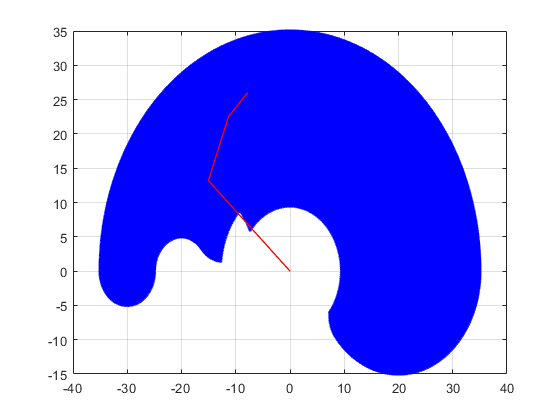


P = [0;0;0;1];
P1 = T_01*P; 
P2 = T_02*P;
P3 = T_03*P;
hold on
plot([0 P1(1) P2(1) P3(1)],[0 P1(2) P2(2) P3(2)], 'LineWidth', 1, 'Color', 'r');
grid on;

% %trajetoria1
% theta1_r= 52;%em graus
% theta2_r= 52;%em graus
% theta3_r= 33.6646;%em graus

%trajetoria2
theta1_r= theta1_d;%em graus
theta2_r= theta2_d;%em graus
theta3_r= theta3_d;%em graus



theta1_r=deg2rad(theta1_r);%em rad
theta2_r=deg2rad(theta2_r);%em rad
theta3_r=deg2rad(theta3_r);%em rad

q_r(:,1)=[theta1_r;theta2_r;theta3_r];

%Definição das velocidade desejadas do efetuador para trajetória Retilínea

dtx_r=diff(tx_r);
dty_r=diff(ty_r);

%Transformada 0-->3:
T03 = [cos(theta1_r+theta2_r+ theta3_r), -sin(theta1_r+theta2_r+ theta3_r), 0, a1*cos(theta1_r)+a2*cos(theta1_r+theta2_r+alfa)+a3*cos(theta1_r+theta2_r+theta3_r);
        sin(theta1_r+theta2_r+ theta3_r), cos(theta1_r+theta2_r+ theta3_r), 0, a1*sin(theta1_r)+a2*sin(theta1_r+theta2_r+alfa)+a3*sin(theta1_r+theta2_r+theta3_r);
        0, 0, 1, 0;
        0, 0, 0,1];

%CONTROLE DE TRAJETÓRIA RETILÍNEA

for i=1:n_pontos_r,
    X_pot_r(:,i)=[a1*cos(q_r(1,i))+a2*cos(q_r(1,i)+q_r(2,i)+alfa)+a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i));
                a1*sin(q_r(1,i))+a2*sin(q_r(1,i)+q_r(2,i)+alfa)+a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i))]; %posição corrente q_p do efetuador
            
    Xd_r(:,i)=[tx_r(i);
        ty_r(i)]; %posicao desejada (pd ou xd)
    
    e_r(:,i)=Xd_r(:,i)-X_pot_r(:,i); %erro de posição(e_p)
    
    if(i<n_pontos_r)
        
        %velocidade pd_ponto (feedfoward)
        dXd_r(:,i)=[dtx_r(i)./dT_r(:,i); dty_r(i)./dT_r(:,i)];
        
        %lei de controle u_p_barra - velocidade linear do efetuador relativo a contribuição da velocidade das juntas
        u_r(:,i)=K_r*e_r(:,i)+dXd_r(:,i);
        
        
        
        jacob = [(-(a1*sin(q_r(1,i))+a2*sin(q_r(1,i)+q_r(2,i)+alfa)+a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i)))), (-((a2*sin(q_r(1,i)+q_r(2,i)+alfa))+(a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i))))), (-a3*sin(q_r(1,i)+q_r(2,i)+q_r(3,i)));
                       (a1*cos(q_r(1,i))+a2*cos(q_r(1,i)+q_r(2,i)+alfa)+a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i))), ((a2*cos(q_r(1,i)+q_r(2,i)+alfa))+(a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i)))), a3*cos(q_r(1,i)+q_r(2,i)+q_r(3,i))];
        jacob_transposta = jacob.';  
        pseudoInv_Jacob = jacob_transposta*(inv(jacob*jacob_transposta));
                 
        %velocidade das juntas qp_ponto=up -> inverso do jacobiano * lei de controle (u = (j(q_p)^-1)
        dq_r(:,i)=pseudoInv_Jacob*u_r(:,i);
        
        %posição corrente q_p
        q_r(:,i+1)=q_r(:,i)+dq_r(:,i)*dT_r(:,i);
        
        %limites mecanicos
        if q_r(1,i+1)>theta1_limSup,%Limite Mecânico Medido
           q_r(1,i+1)=theta1_limSup;
        end
        if q_r(1,i+1)<theta1_limInf, %Limite Mecânico Medido
           q_r(1,i+1)=theta1_limInf;
        end
        if q_r(2,i+1)>(theta2_limSup-pi/2), %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limSup;
        end
        if q_r(2,i+1)<(theta2_limInf-pi/2), %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limInf;
        end
        if q_r(3,i+1)>theta3_limSup, %Limite Mecânico Medido
           q_r(3,i+1)=theta3_limSup;
        end
        if q_r(3,i+1)<theta3_limInf, %Limite Mecânico Medido
           q_r(3,i+1)=theta3_limInf;
        end
    end
end

%Gráfico da Trajetória Retilínea juntamente com Espaço de Trabalho

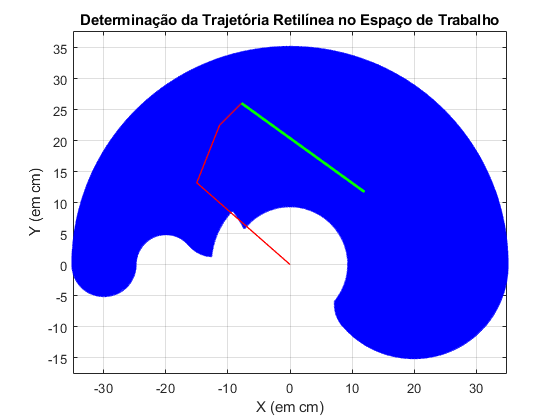

plot(tx_r,ty_r,'g', "LineWidth",2);
xlabel('X (em cm)'), ylabel('Y (em cm)'), title('Determinação da Trajetória Retilínea no Espaço de Trabalho');
axis equal;

%Conversão de Radianos para Graus

q_r=rad2deg(q_r); %Variáveis de Juntas para Trajetória Retilínea
dq_r=rad2deg(dq_r); %Velocidades das Juntas para Trajetória Retilínea

%Gráficos Pedidos

%********Trajetória Desejada X Trajetória Efetuada*************************

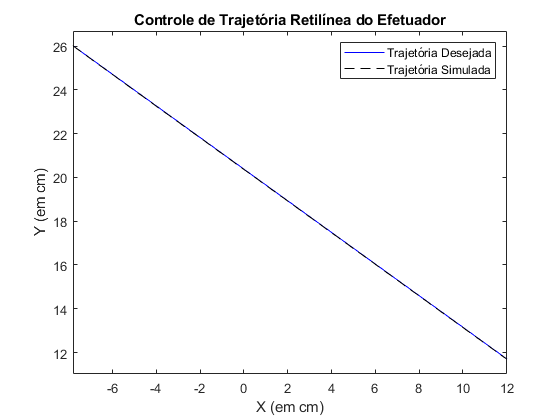

%Trajetória Retilínea
figure,
plot(tx_r,ty_r,'b',X_pot_r(1,:),X_pot_r(2,:),'k--');
ylabel('Y (em cm)'), xlabel('X (em cm)'), title('Controle de Trajetória Retilínea do Efetuador');
legend('Trajetória Desejada','Trajetória Simulada');
axis equal

%********Posições Angulares das Juntas X Tempo*****************************

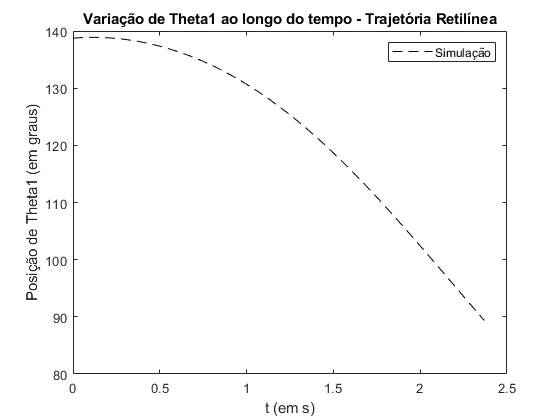

%Trajetória Retilínea
figure,
plot(T_r,q_r(1,:),'k--');
ylabel('Posição de Theta1 (em graus)'), xlabel('t (em s)'), title('Variação de Theta1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

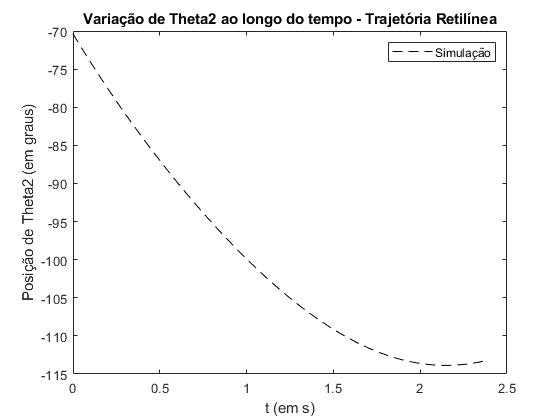

%axis equal;
figure,
plot(T_r,q_r(2,:),'k--');
ylabel('Posição de Theta2 (em graus)'), xlabel('t (em s)'), title('Variação de Theta2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

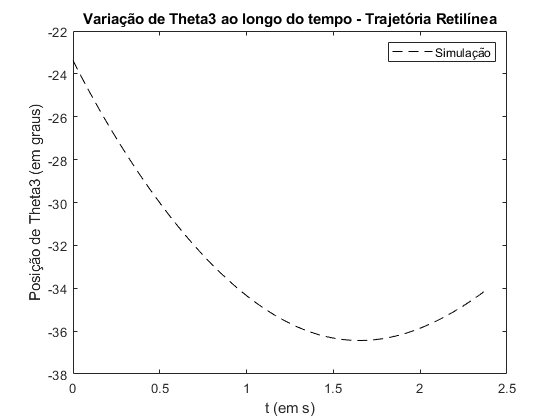

%axis equal;

figure,
plot(T_r,q_r(3,:),'k--');
ylabel('Posição de Theta3 (em graus)'), xlabel('t (em s)'), title('Variação de Theta3 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

%axis equal;

%********Erro de Posição X Tempo*******************************************

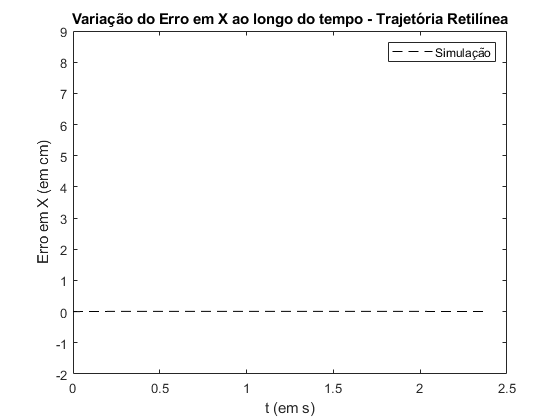

%Trajetória Retilínea
figure,
plot(T_r,e_r(1,:),'k--');
ylabel('Erro em X (em cm)'), xlabel('t (em s)'), title('Variação do Erro em X ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-2,9]);

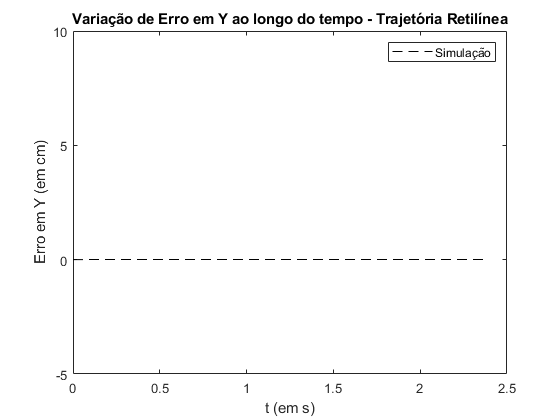

%axis equal;
figure,
plot(T_r,e_r(2,:),'k--');
ylabel('Erro em Y (em cm)'), xlabel('t (em s)'), title('Variação de Erro em Y ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-5,10]);

%axis equal;

%********Velocidade das Juntas X Tempo*******************************************

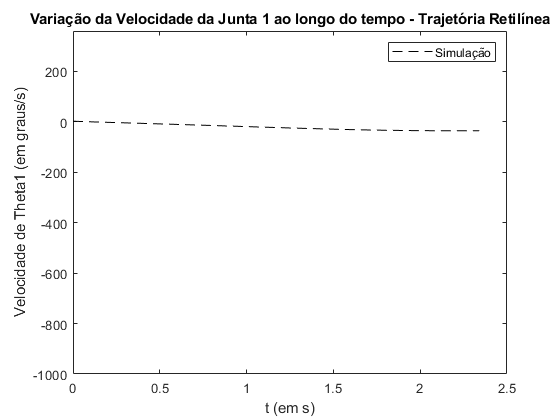

%Trajetória Retilínea
figure,
plot(T_r(1:n_pontos_r-1),dq_r(1,:),'k--');
ylabel('Velocidade de Theta1 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-1000,360]);

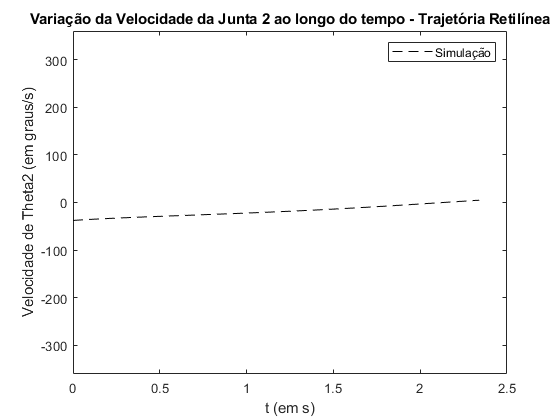

%axis equal;
figure,
plot(T_r(1:n_pontos_r-1),dq_r(2,:),'k--');
ylabel('Velocidade de Theta2 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-360,360]);

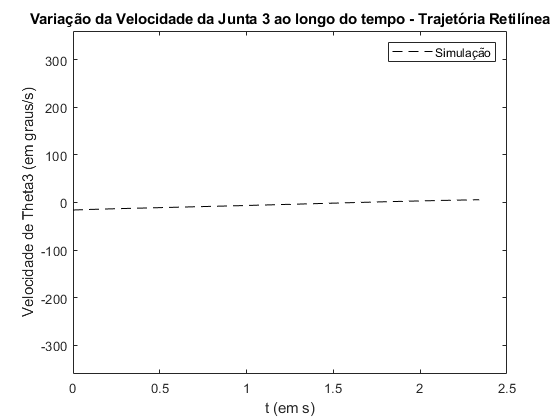

%axis equal;
figure,
plot(T_r(1:n_pontos_r-1),dq_r(3,:),'k--');
ylabel('Velocidade de Theta3 (em graus/s)'), xlabel('t (em s)'), title('Variação da Velocidade da Junta 3 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');
axis([0,2.5,-360,360]);

%axis equal;